Support Vector Machine (SVM) is a powerful and versatile supervised machine learning algorithm used primarily for classification and regression tasks. Here's an overview of how SVM works and its key concepts:Key Concepts

- **Classification and Regression:** SVM can be used for both classification (SVM) and regression (SVR for Support Vector Regression). In classification, the goal is to find the best hyperplane that separates different classes with the maximum margin. In regression, it tries to fit the best line within a threshold error.

- **Hyperplane:** In SVM, a hyperplane is a decision boundary that separates different classes. In a two-dimensional space, this hyperplane is a line, but in higher dimensions, it becomes a plane or a hyper-surface.

- **Margin**: This is the gap between the hyperplane and the nearest data points from each class. Maximizing this margin is key to improving the classifier's performance and generalization ability.

- **Support Vectors:** These are data points that are closest to the hyperplane and influence its position and orientation. They are pivotal in constructing the hyperplane because the margin is calculated based on these points.

- **Kernel Trick: **SVM uses a technique called the kernel trick to handle non-linear input spaces. This allows the algorithm to find a linear separation in a higher-dimensional space without computing the coordinates in that space directly. Common kernels include linear, polynomial, radial basis function (RBF), and sigmoid.

**How SVM Works**

- Linear SVM: In its simplest form, for linearly separable data, SVM finds a straight line (in two dimensions) or a hyperplane in higher dimensions that best divides the classes.

- Non-linear SVM: When data is not linearly separable, SVM uses kernel functions to transform the input data into a higher-dimensional space where a linear hyperplane can be used to separate the classes.

**Real-Life Example: Credit Risk Assessment**

- **Data Preparation:** The bank collects and prepares data where each attribute is turned into a numerical value. For instance, employment history might be encoded as the number of years, and credit history could be the number of credit problems in the past.

- **Model Training:** Using historical data, the bank trains an SVM model. The data points (customers) that are hardest to classify play a crucial role in determining the hyperplane because they are the support vectors.

- **Classification**: Once the SVM model is trained, it can be used to predict whether a new customer will default on a loan. The SVM will classify the new customer based on where they fall relative to the decision boundary defined by the hyperplane.

- **Decision Making:** Based on the prediction, the bank can make a more informed decision about whether to approve the loan. If the SVM predicts a high risk of default, the loan application might be rejected or given under stricter terms.

**Conclusion**

In this example, the SVM algorithm helps the bank to effectively segregate risky loan applicants from safer ones based on historical data. This is crucial for minimizing the risk of bad debt and for financial planning. The use of SVM in this context is justified by its ability to handle complex, multi-dimensional data and classify new instances with high accuracy, making it a valuable tool in the risk management toolkit.

**Implementation In Matlab:**

To implement the SVM for a credit risk assessment scenario in MATLAB, we can use the built-in functions from the Statistics and Machine Learning Toolbox. This example will demonstrate a simplified version where we simulate data for loan applications with features that might influence the credit risk (e.g., income, credit score) and then use SVM to classify the applicants.

**Step 1: Generate Simulated Data**

% Number of samples
numSamples = 1000;

% Generate random income between 30k to 100k
income = 30000 + (100000-30000).*rand(numSamples,1);

% Generate random credit scores between 300 to 850
creditScore = 300 + (850-300).*rand(numSamples,1);

% Assume a simple rule: higher income and credit score generally mean lower risk
% We add random noise to make it non-linearly separable
defaultRisk = income + 0.5 * creditScore + 10000*randn(numSamples,1);

% Label: 1 for low risk, 0 for high risk
labels = double(defaultRisk > median(defaultRisk));

**Step 2: Prepare Data for SVM**

We need to split our data into training and testing datasets.

% Split data into training and testing sets (70% train, 30% test)
cv = cvpartition(numSamples, 'HoldOut', 0.3);
idxTrain = training(cv);
idxTest = test(cv);

% Training data
XTrain = [income(idxTrain), creditScore(idxTrain)];
YTrain = labels(idxTrain);

% Testing data
XTest = [income(idxTest), creditScore(idxTest)];
YTest = labels(idxTest);

**Step 3: Train SVM Classifier**

We will use the `fitcsvm` function to train the SVM model.

% Train the SVM classifier
svmModel = fitcsvm(XTrain, YTrain, 'KernelFunction', 'linear', 'BoxConstraint', 1);

**Step 4: Predict and Evaluate the Classifier**

Now, use the trained model to predict the test data and evaluate its performance.

% Predict using the SVM model
YPred = predict(svmModel, XTest);

% Calculate accuracy
accuracy = sum(YPred == YTest) / length(YTest);
fprintf('Accuracy of SVM model: %.2f%%\n', accuracy * 100);

Accuracy of SVM model: 84.00%


**Step 5: Visualize the Decision Boundary**

Visualizing the decision boundary can help understand how the SVM classifier separates the classes.

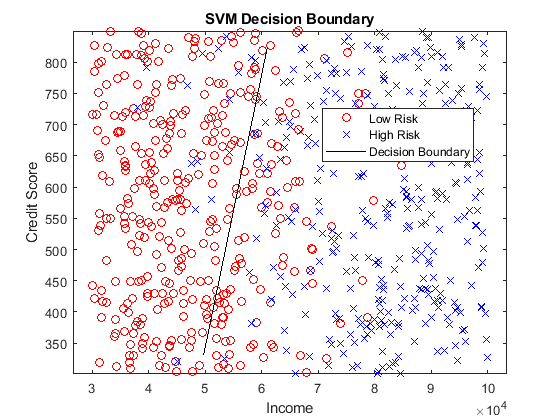

% Plotting the data and the decision boundary
figure;
gscatter(XTrain(:,1), XTrain(:,2), YTrain, 'rb', 'ox');
hold on;

% Adjust the range and resolution of the meshgrid
d = 1;  % Adjust this value as necessary to manage computational load
incomeRange = [prctile(XTrain(:,1), 5), prctile(XTrain(:,1), 95)];
creditScoreRange = [prctile(XTrain(:,2), 5), prctile(XTrain(:,2), 95)];
[x1Grid, x2Grid] = meshgrid(linspace(incomeRange(1), incomeRange(2), round((incomeRange(2)-incomeRange(1))/d)), ...
                            linspace(creditScoreRange(1), creditScoreRange(2), round((creditScoreRange(2)-creditScoreRange(1))/d)));

% Create grid for prediction
xGrid = [x1Grid(:), x2Grid(:)];
[~,scores] = predict(svmModel, xGrid);

% Plot decision boundary
contour(x1Grid, x2Grid, reshape(scores(:,2), size(x1Grid)), [0, 0], 'k');

% Labels and legends
xlabel('Income');
ylabel('Credit Score');
title('SVM Decision Boundary');
legend('Low Risk', 'High Risk', 'Decision Boundary', 'Location', 'Best');
hold off;

**Sample MATLAB Code for SVM with Cross-Validation and Parameter Tuning**

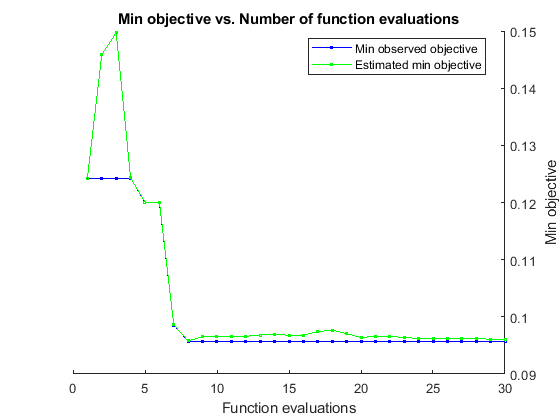

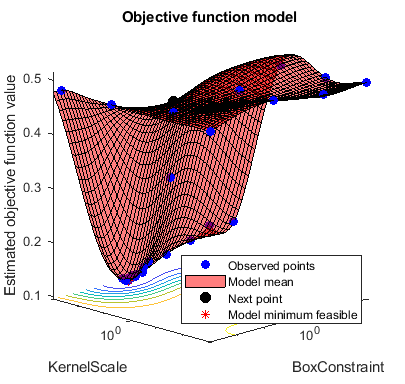

|=====================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   | BoxConstraint|  KernelScale |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |
|=====================================================================================================|
|    1 | Best   |     0.12429 |     0.75434 |     0.12429 |     0.12429 |       2.2461 |       482.01 |
|    2 | Accept |     0.48429 |     0.48681 |     0.12429 |     0.14587 |    0.0010316 |       474.63 |
|    3 | Accept |     0.48429 |     0.63317 |     0.12429 |     0.14971 |       53.014 |    0.0025241 |
|    4 | Accept |     0.48429 |     0.53452 |     0.12429 |     0.12432 |     0.004399 |      0.10925 |
|    5 | Best   |        0.12 |     0.48177 |        0.12 |     0.12006 |       1.0646 |       364.44 |
|    6 | Accept |        0.29 |     0.59856 |        0.12 |     

% Assuming XTrain, YTrain are your training features and labels

% Set up partition for cross-validation
c = cvpartition(YTrain, 'KFold', 10);

% Set up the parameter grid to search
opts = struct('Optimizer','bayesopt','ShowPlots',true,'CVPartition',c,...
    'AcquisitionFunctionName','expected-improvement-plus');

% Train the SVM model with kernel and box constraint tuning
svmModel = fitcsvm(XTrain, YTrain, 'KernelFunction','rbf', ...
    'OptimizeHyperparameters',{'BoxConstraint', 'KernelScale'}, ...
    'HyperparameterOptimizationOptions',opts);


% Predict using the optimized SVM model
YPred = predict(svmModel, XTest);

% Calculate accuracy and other metrics
accuracy = sum(YPred == YTest) / length(YTest);
confMat = confusionmat(YTest, YPred);
fprintf('Accuracy of optimized SVM model: %.2f%%\n', accuracy * 100);

Accuracy of optimized SVM model: 87.33%



% Display the confusion matrix
disp('Confusion Matrix:');

Confusion Matrix:


disp(confMat);

   122    17
    21   140

